# **Intro to MATLAB Workshop**

**Written by Ian Harris**

## Getting Familiar with the MATLAB Interface

MATLAB has 3 main interface components, plus the toolbar up top. There is:

- Command Window: default is the bottom of the screen --> this is where all output messages are displayed. Test code can also be run in the CW as well. 

- Workspace: default is to the right side of the screen --> this is where all variables, arrays, anonymous functions, etc. are contained after creation. They can be accessed by double-clicking the variable.

- Folder Directory: default is to the left side of the screen --> this is where directory navigation functionality is utilized. User can switch between folders for access to different scripts, etc.

On the top toolbar, there is quite a lot to unfold. The main buttons needed for now are the run, save, and new buttons. You can also click and drag each of the 3 main interface components to your liking as well.

## Variables and Operators

### Variables

Let's first start by defining a variable. A variable can be called anything as long as it starts with a letter and contains only alphanumeric characters and '_' .

What would be a valid variable?

- x

- pizza

- 8dice

- hugh_jackman

- fruit-salad

- &*@&$^@(@

- tacoTuesday

If you said 1, 2, 4, and 7 then you got it! Now, let's define one of these variables.

x = 2

x = 2

x

x = 2

Notice how x is printed to the command window (or below the code block if in a live script). Let's mute this! We can do this using a semicolon.

x = 2;
y = 5;
z = 21;

Make sure to run the code to enter those values into the system! Now, let's learn about some different variable types.

### Variable Types

There are 5 main variables types:

- Integer

- Float

- Boolean

- String

- Character Array

Let's define some of those now.

% Integer
integer = 5;

% Float
float = 7.92839582;

% Boolean
boolean = true; % either true / false or 1 / 0

% String
string = "this is a string";

% Character
character = 'this is a character array';

NOTE: Strings are not the same as character arrays, there are many differences between the two; we will touch on this later!

### Operators

Now, let's learn some PEMDAS operators!

% Earlier we had:
%    x = 2;
%    y = 5;
%    z = 21;

x + y

ans = 7

2 - z

ans = -19

4 * x

ans = 8

x / 4

ans = 0.5000

8 * ( 2 - x )

ans = 0

x^2

ans = 4

### ceil() / floor()

What if when adding numbers together, we want to round up or down? Good question! We can use

- ceil() to round numbers up, and

- floor() to round numbers down.

Let's try it.

fc_var = 4.578;
ceil(fc_var)

ans = 5

floor(fc_var)

ans = 4

Notice, ceil() and floor() do not do anything when an integer is inputed.

floor(4)

ans = 4

### Strings and Characters Comparison

What would happen if we tried adding characters and strings? Let's try it!

s1 = "Hello ";
s2 = "World";

s3 = s1 + s2

s3 = "Hello World"

s1c = 'Hello ';
s2c = 'World';

% s3c = s1c + s2c

Well that did not work to plan for adding character arrays. What gives? Let's look a bit deeper.

length(s1)

ans = 1

length(s2)

ans = 1

length(s3)

ans = 1

length(s1c)

ans = 6

length(s2c)

ans = 5

Now what if we try modifying the length of s1c?

s1c = 'Hello';

s3c = s1c + s2c

s3c =    159   212   222   216   211


Whoah now, we added a string, but now we're getting numbers! What's the catch??

What these numbers are are ASCII values. For each letter, number, and character inside of a string, there is an associated numeric value for each digit. A list of them can be found [here.](https://www.matrixlab-examples.com/ascii-chart.html)

What is useful about ASCII values is they can be used for passwords and incripting messages, but that is for another workshop!

### Adding Different Variable Types

Now, what happens if we add different variable types? Let's say an integer and a string?

x + s2

ans = "2World"

What is happening here is MATLAB is switching x into a string to make it compatible, but we can specify x as only an integer using int().

% int(x) + s2

We can use the command such as num2str() to convert an integer to a character array.

num2str(x)

ans = '2'

There are many more, so feel free to explore the different data type conversion commands!

## Printing to the CW

Is your workspace getting clustered? Let's fix that. Try entering 'clear' in the CW. Now is your CW getting clustered? Try entering 'clc' in the CW. 

% In the CW, enter:
%
%   'clear'
%
% to clear your workspace

% In the CW, enter:
%
%   'clc'
%
% to clear your CW

Now that we can keep a clean space, let's get printing!

### disp()

Let's learn one of our printing functions.

% Define parameters
age = 21;
text = "Happy Birthday!";

disp("On my " + age + " st birdthday, people shouted " + text)

On my 21 st birdthday, people shouted Happy Birthday!


### fprintf()

Now let's learn another printing function!

fprintf("On my %i st birthday, people shouted %s", age, text)

On my 21 st birthday, people shouted Happy Birthday!

What if we want to get very specific with our birthday?

age = 21.37583;
fprintf("On my %.2i st birthday, people shouted %s", age, text)

On my 2.14e+01 st birthday, people shouted Happy Birthday!

fprintf("On my %10.2i st birthday, people shouted %s", age, text)

On my   2.14e+01 st birthday, people shouted Happy Birthday!

The first number before the period specifies the total allocated spaces for that integer/float/etc and the number after the period specifies to what decimal point the number is rounded to.

## Conditional Statements

With conditional statements, we can start to filter through our data to get different outcomes.

a = 6;
if a > 5
    disp("a is greater than 5")
end

a is greater than 5


But what if we want to have a backup incase the if is not met?

b = 4;
if b > 5
    disp("b is greater than 5")
else
    disp("b is less than 5")
end

b is less than 5


However, what if we have multiple conditions?

c = 5;
if c > 5
    disp("c is greater than 5")
elseif c < 5
    disp("c is less than 5")
else
    disp("c is equal to 5")
end

c is equal to 5


## Loops

### For Loop

Let's try setting up a for loop.

for i = 1:3
    disp(i)
end

     1
     2
     3


arr = [1 2 3 4 5];
for i = 1:length(arr)
    disp( arr(i) )
end

     1
     2
     3
     4
     5


### While Loop

Now, let's try setting up a while loop.

j = 1

j = 1

while j < 5
    disp(j)
    j = j + 1;
end

     1
     2
     3
     4


Make sure to increment j, or have some stopping point in place, otherwise the while loop could go on forever!

## Functions

### Internal-Stored Functions

We can store functions at the bottom of our MATLAB scripts. They must be after the actual function call, that is why they are often placed at the bottom of the script. For example, a function was placed/or will be added at the bottom of the script called 'sumup' and it has two inputs: a and b with an output of x. Let's use it!

x = sumup(5, 2)

x = 7

### External-Stored Functions

We can also create functions externally from our script. These can either be stored in the same directory folder, or in another folder, but then the folder path will have to be added. Let's create a new external function in our main folder called 'mult'.

So, now that our function 'mult(a,b)' is defined, one handy thing we can do to get more info for the function is by using 'type' with our function name. Let's use it for 'mult(a,b)'.

type mult

function x = mult(a,b)

    x = a * b;

end


NOTE: All external function file names must be named the same as the function name! That is why the function 'mult' has the file name 'mult.m'.

### Anonymous Functions

Now let's say we don't want to create a function file for a shorter function, then we could use an anonymous function. Let's make one to calculate y values for the function $y\left(x\right)=x^3 -4x^2 +2$ .

f = @(x) x.^3 - 4*x.^2 + 2;
f(3)

ans = -7

### Scope

Now that we started talking about functions, let's talk about scope. There are two kinds of scope: local and global. With functions, they utilize both local and global scopes. Let's see how.

globalVar = 10; % this has global scope

disp(globalVar)

    10


printGlobalVar()

     5


Inside of the printGlobalVar() function, globalVar was defined, but it was only a local variable within that function. What that means is it's independent from anything else going on inside of your script. It is separate from whatever else was defined in your main script file. This is a handy thing to get used to for optimizing your code.

### Adding Folder Paths

One incredibly useful tip is learning how to add folder paths to MATLAB. The default path is to the opened folder in the folder directory. Typically, only the scripts/functions in that folder can be accessed when opened, but one can create a folder and add it to the path so all of the handy functions and scripts in it can be accessed from any other folder!

The steps to do this are as so:

- Go to the 'Home' tab.

- Look towards the middle-right side of the top toolbar to find a button called 'Set Path'.

- Once selected, a pop-up will appear, then click 'Add Folder'.

- Select a folder you want to add to the path and then click 'Save', then you're done! Congrats!

Now go ahead and add a function file to that folder and try calling it in a script located in a different folder.

## Arrays

Now that we know how to create data variables, let's learn different ways to store them to make our data better accessible and easier to work with. The first up is an array.

### Creating Arrays

An array is a collection of data stored between two square brackets: [ ] . Let's make some.

arr = [1 2 3 4]

arr =      1     2     3     4


arr2 = [1,2,3,4]

arr2 =      1     2     3     4


Notice, we can use either spaces or commas to separate array values.

Arrays can contain numbers, strings, characters, boolean, or all of the above!

arr3 = [1 "hello" true 'characters']

arr3 = 1×4 string array
    "1"    "hello"    "true"    "characters"

We can also create arrays using two handy features. Let's look at them first, and then talk about the features.

x1 = 1:2:10 % start:step:end

x1 =      1     3     5     7     9


x2 = linspace(0,2*pi,361) % start, end, numOfDataPoints

x2 =          0    0.0175    0.0349    0.0524    0.0698    0.0873    0.1047    0.1222    0.1396    0.1571    0.1745    0.1920    0.2094    0.2269    0.2443    0.2618    0.2793    0.2967    0.3142    0.3316    0.3491    0.3665    0.3840    0.4014    0.4189    0.4363    0.4538    0.4712    0.4887    0.5061    0.5236    0.5411    0.5585    0.5760    0.5934    0.6109    0.6283    0.6458    0.6632    0.6807    0.6981    0.7156    0.7330    0.7505    0.7679    0.7854    0.8029    0.8203    0.8378    0.8552


For the first feature, it has this format - start:step:end. So, using the first example, we started at 1, went in steps of 2, and ended at 10. However, the last value was 9 in the array x1. This is because if we were to step another 2, we'd be at 11, which is over our end value 10, so 9 is the last value.

For the second feature, linspace(), it has the format - start,end,numOfDataPoints. In the second example, we started at 0, ended at $2\pi$, and we did this with 361 data points. Both of these make array creation easier for simplier arrays and are a nifty additiion to the MATLAB toolset!

Now, what about editing array data?

### Editing Arrays

To edit an array value, we can simply use the index from 1 to the number of entries of the array.

arr, ...
arr(2) = 5

arr =      1     2     3     4


arr =      1     5     3     4


See, not too bad, huh? But what if we want to change the last value of an array but we don't know how long an array is and we don't want to use the length() function (which tells us the length of the array!), then we can use the (end) index command.

arr, ...
arr(end) = 21

arr =      1     5     3     4


arr =      1     5     3    21


Now, what if we want to insert a value rather than replace it?

arr4 = [1 2 3 5 6 7];

We have defined an array that runs from 1-7, but it is missing 4! What we can do, is use is the ':' as well as square brackets to help us insert that 4 where it belongs.

arr4 = [arr4(1:3) 4 arr4(4:end)]

arr4 =      1     2     3     4     5     6     7


Okay, so there is a lot going on here. Let's break it down. So we are starting off by writing an outer set of square brackets. This creates a new space for an array to be defined. Inside of that new array, we start out with 

which takes the 1st value of arr4 to the 3rd value of arr4 and inserts it into the new array. We then have a 4 which follows the first three values of arr4. After that, we used 

to then add the rest of arr4 to complete our array going from 1 to 7!

It should be pointed out, notice how our final value in arr3 was a character array (denoted by the single quote) but was converted into a string (denoted by double quotes). Interesting right? Now, check this out.

arr_char = ['test' 'haha' 'banana']

arr_char = 'testhahabanana'

We can see arr_char simply concatenated our character arrays together into one larger character array. This is because character arrays are arrays, and from what we learned with arr4, we can concatenate or append arrays together using square brackets. This is one of the important differences between character arrays and strings. Strings are treated as one single object, or scalar quantities while character arrays have length because they are vectors.

### Handy Built-In Functions

Let's say we have an array of test scores. How can we find some statistics about the scores?

scores = [78 99 37 56 88 89 95 92 79 68 94 83];

% Find maximum of scores
max(scores)

ans = 99

% Find minimum of scores
min(scores)

ans = 37

% Find average of scores
mean(scores)

ans = 79.8333

% Find standard deviation of scores
std(scores)

ans = 18.2250

We can also find the sum of the scores as well using the 'sum()' function.

sum(scores)

ans = 958

## Matrices

### Creating Matrices

Now that we have learned to create arrays, let's create matrices. We can think of arrays as 1-dimensional and matrices as 2-dimensional objects. Now, let's make a matrix.

mat = [1 2; 3 4]

mat =      1     2
     3     4


mat2 = [ 4 3
         2 1 ]

mat2 =      4     3
     2     1


Notice we can define matrices several different ways. For the inline definition of a matrix, you can use spaces or commas to separate columns and ' ; ' to separate rows. Another way to define a matrix would be to indent to a new line each time you have a row. 

Again, matrices can have other values besides numbers. However, notice that if we define a character array, this doesn't work... intriguing right?

% mat3 = ["hello" 3; true 'char']

The reason for this is because it is trying to add an array within a matrix which does not work (but it does work for cell arrays, wink wink). That is why in 'Strings and Characters Comparison' we found strings and character arrays have different lengths for the same phrase, they just have different meanings to MATLAB. If we intead use a string, it works like a charm.

mat3 = ["hello" 3; true "char"]

mat3 = 2×2 string array
    "hello"    "3"   
    "true"     "char"

### Editing Matrices

Now that we are getting more comfotable with creating matrices, let's learn how edit the data stored within a matrix.

mat, ...
mat(1,2) = 3 % order is (row #, col #)

mat =      1     2
     3     4


mat =      1     3
     3     4


The format for changing a matrix value is similar to changing an array, except we have a row number and a column number to access that specific value's position.

### Creating Matrix from Arrays

One handy thing we can do with arrays is turn them into matrices by appending them.

% Define arrays
arr = [1 2 3 4];
arr2 = [5 6 7 8];
arr3 = [9 10 11 12];

mat4 = [ arr; arr2; arr3]

mat4 =      1     2     3     4
     5     6     7     8
     9    10    11    12


mat5 = [arr' arr2' arr3']

mat5 =      1     5     9
     2     6    10
     3     7    11
     4     8    12


As we can see, there are many different ways to manipulate arrays when concatenating them into matrices. Notice how mat4 is the transpose of mat5. In MATLAB, this can be done using an apostrophe.

mat4', ...
mat5

ans =      1     5     9
     2     6    10
     3     7    11
     4     8    12


mat5 =      1     5     9
     2     6    10
     3     7    11
     4     8    12


Now, this is more of a math tid-bit, but the apostrophe in MATLAB is used as the Hermitian. What this means is if all matrix/array values are real, all that is done is the transponse is taken, but if there are some imaginary values, then the transpose will take place, but only after the complex conjugate is taken for each value. Pretty cool, huh!

### Handy Built-In Functions Matrix Application

In the array section, we learned about some handy functions. Let's try them again with matrices now.

mat6 = [ 34  5  7 28
         82 76 19  4
         12  1 41  8 ]

mat6 =     34     5     7    28
    82    76    19     4
    12     1    41     8


% Find maximum
max(mat6) % by col

ans =     82    76    41    28


max(mat6,[],2), ... % by row
max(mat6')

ans =     34
    82
    41


ans =     34    82    41


% Find minimum
min(mat6) % by col

ans =     12     1     7     4


min(mat6,[],2), ... % by row
min(mat6')

ans =      5
     4
     1


ans =      5     4     1


% Find average
mean(mat6) % by col

ans =    42.6667   27.3333   22.3333   13.3333


mean(mat6,2), ... % by row
mean(mat6')

ans =    18.5000
   45.2500
   15.5000


ans =    18.5000   45.2500   15.5000


% Find standard deviation
std(mat6) % by col

ans =    35.7957   42.1940   17.2434   12.8582


std(mat6,[],2), ... % by row
std(mat6')

ans =    14.6629
   39.5253
   17.5973


ans =    14.6629   39.5253   17.5973


### Solving Linear Systems using Matrices

It would bad teaching on my part if you were not shown how to solve linear systems using matrices, after all, the 'MAT' in MATLAB stands for matrix. Let's set up a system of equations as so: $\left\lbrack \begin{array}{cc}
2 & 9\\
-3 & 4
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x\\
y
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
10\\
3
\end{array}\right\rbrack$. Since we know $\mathrm{Ax}\;"="\;b$ , we can use MATLAB's ' \ ' operator to help us solve for x and y. Typically, we would solve $\mathrm{Ax}\;"="\;b$ by taking the inverse of A to get $x\;"="\;A^{-1} b$ . It so happens that $A^{-1} b$ stands for $A\backslash b$ in MATLAB. Let's try this out!

% Define parameters
A = [  2 9
      -3 4 ];
b = [10 3]';

% Solve for x
x = A\b

x =     0.3714
    1.0286


So, we get that $x\approx 0\ldotp 3714$ and $y\approx 1\ldotp 0286$ . Pretty handy, right!

## Cell Arrays

### Creating Cell Arrays

Next up in our data structures are cell arrays. Cell arrays are unique because they allow users to store individual values, arrays, and even matrices within each entry! You can even store cell arrays within cell arrays! Cell arrays are accessed by using curly braces ' {  } '. Let's experiement with one!

cell_arr = {3 "hello" [1 2 3] 'tacos' [4 5 6;7 8 9] {2}}

cell_arr = 1×6 cell array
    {[3]}    {["hello"]}    {[1 2 3]}    {'tacos'}    {2×3 double}    {1×1 cell}

Cell arrays are incredibly adaptable for most tasks. One thing that should be noted is the 4th entry is a character array and it remained intact; it was not converted into a string for compatibility! This aids the problem we had before when trying to create arrays full of character arrays because MATLAB concatenated the arrays together into one larger array, but now we can store character arrays in cell arrays and keep the information separated!

cell_arr2 = {'this' 'is' 'a';'cell' 'array' '!'}

cell_arr2 = 2×3 cell array
    {'this'}    {'is'   }    {'a'}
    {'cell'}    {'array'}    {'!'}

Here is an example of a 2-dimensional cell array. To start a new row, you can use a semicolon like before.

### Editing Cell Arrays

To edit cell arrays, it is similar to matrices and arrays, except we would need to use curly braces instead of parenthesis. Here are two examples of this.

cell_arr, ...
cell_arr{2} = 439

cell_arr = 1×6 cell array
    {[3]}    {["hello"]}    {[1 2 3]}    {'tacos'}    {2×3 double}    {1×1 cell}

cell_arr = 1×6 cell array
    {[3]}    {[439]}    {[1 2 3]}    {'tacos'}    {2×3 double}    {1×1 cell}

cell_arr2, ...
cell_arr2{end,end} = '!!!!!'

cell_arr2 = 2×3 cell array
    {'this'}    {'is'   }    {'a'}
    {'cell'}    {'array'}    {'!'}

cell_arr2 = 2×3 cell array
    {'this'}    {'is'   }    {'a'    }
    {'cell'}    {'array'}    {'!!!!!'}

If you see with the second example, we got a little sneaky there by using

instead of using

Either does the trick, but the first is less prone to mistakes!

## Structs

### Creating Structs

The 4th and final data structure that we will learn about is a structure. If you are familiar with python classes and subclasses, then this data structure will feel very familiar, but if you are not familiar with python classes then have no fear, for learning time is here! There are a few different ways to create structures. Let's see a few.

single_pizza.numOfSlices = 8;
single_pizza.topping = "cheese";
single_pizza

single_pizza = struct with fields:
    numOfSlices: 8
        topping: "cheese"

pizza.numOfSlices = [6 8 10];
pizza.topping = ["cheese" "pepperoni" "hawaiian"]

pizza = struct with fields:
    numOfSlices: [6 8 10]
        topping: ["cheese"    "pepperoni"    "hawaiian"]

st = struct('x',{'a','b'},'y','c')

st = 1×2 struct array with fields:
    x
    y

### Editing Structs

To edit a struct, we can simply override the value by listing the same path to that value. Let's use the struct 'st' from above to do this.

st, ...
st(2).y = 'd'

st = 1×2 struct array with fields:
    x
    y

st = 1×2 struct array with fields:
    x
    y

## Visualization

The final topic for this workshop is data visualization using graphs. For this section, we will be talking about how to plot functions on line plot and how to annotate the graph. Let's start with an anonymous function to get some data.

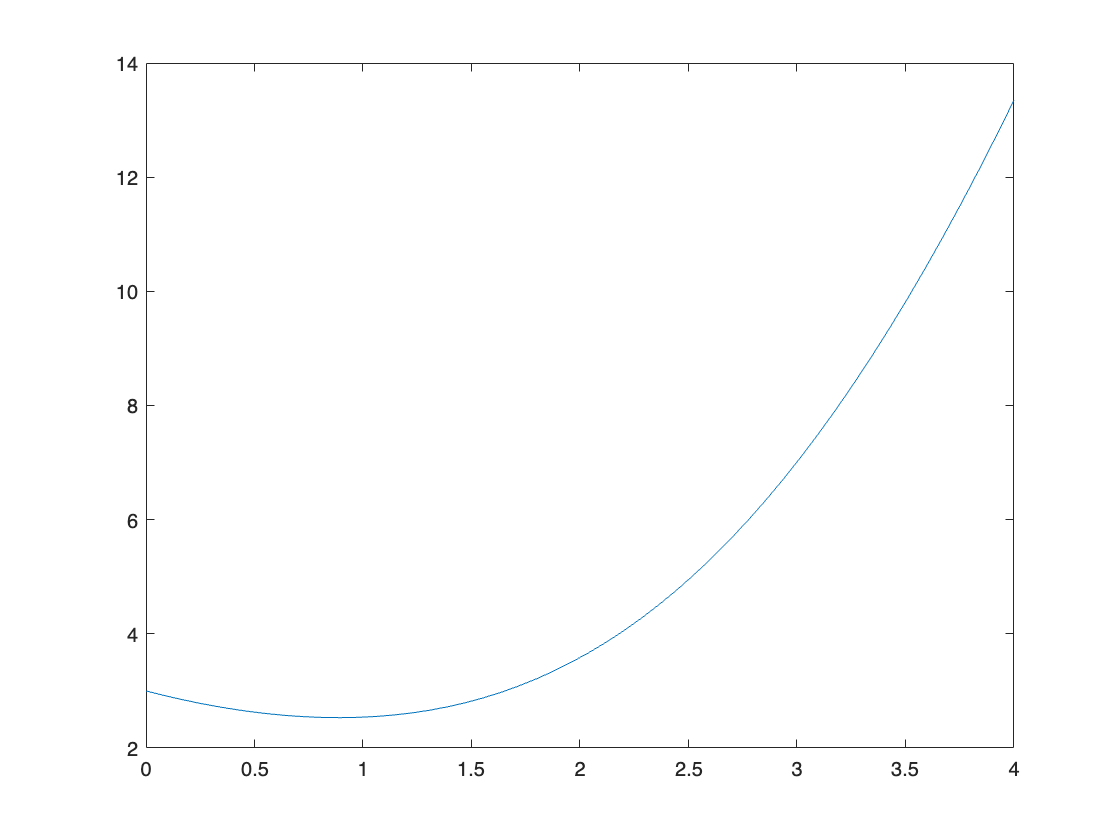

x = linspace(0,4,50);
g = @(x) cos(x) + x.^2 - x + 2;

clf
plot(x,g(x))

Yay, we made our first plot! But what if we want to add labels to it?

clf
plot(x,g(x))
title("Graph!")
xlabel("x")
ylabel("y")

But hold on, what if we do multiple functions? How would we tell them apart?

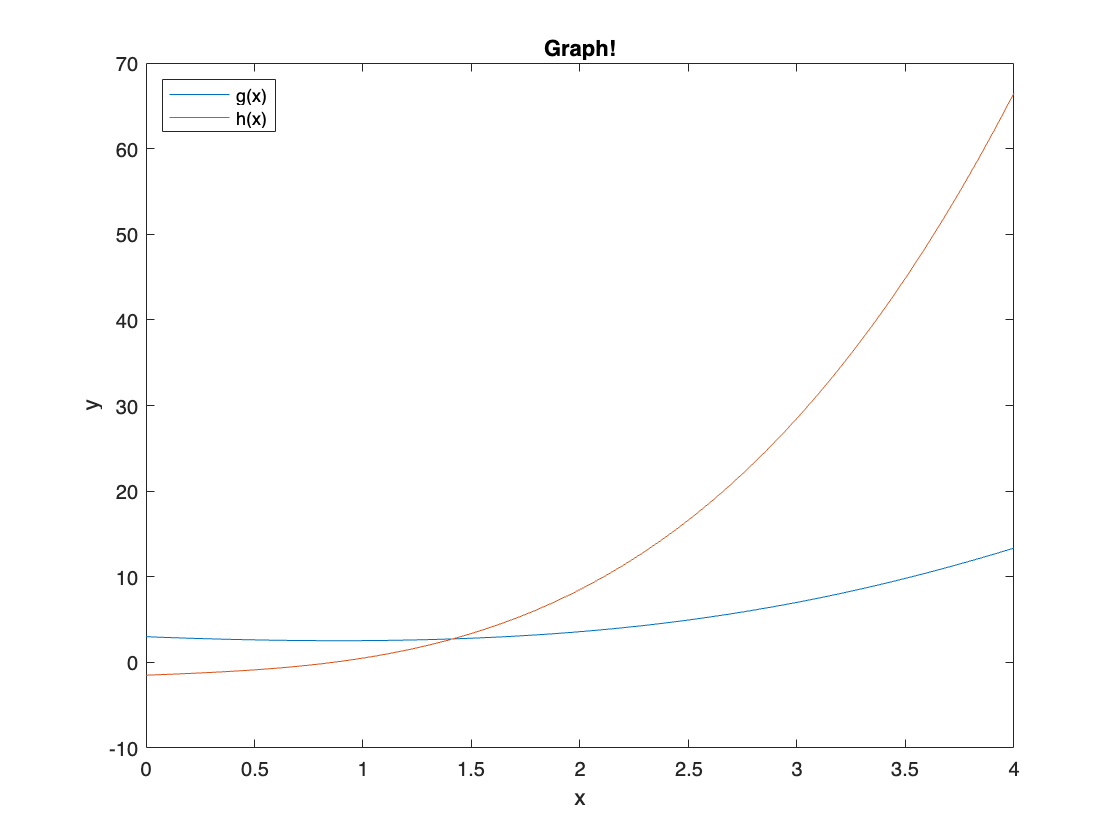

hold on
h = @(x) x.^3 + x - 1.5;

plot(x,h(x))
legend("g(x)","h(x)",'Location','northwest')

What we can do is use the phrase 'hold on' to indicate to MATLAB that we'd like to add another function to the previous graph. Notice we also used 'clf' before we plotted to clear all figure presets from prior graphs and figures. This isn't necessary for functionality, but if any quirks occur, that would be the best bet to try first!

We can also use the legend to include the label for each function as well as control where the legend is. Another thing to explore on your own or in other MATLAB workshops is how to change line color and width as well as plotted data point shapes.

**This concludes the Intro to MATLAB Workshop. Thank you for following along and hopefully this helped with your journey into programming!**

## Internal Functions

function x = sumup(a,b)

    x = a + b;

end

function printGlobalVar()

    globalVar = 5; % this has local scope
    disp(globalVar)

end